# Robot Navigation Project - View Sequence Data

robods = signalDatastore("../data/robotdata", "SignalVariableNames", ["front" "left"], "ReadOutputOrientation", "row");
transds = transform(robods, @prepsig);
sigdata = readall(transds);

labelds = signalDatastore("../data/robotdata", "SignalVariableNames", "direction")

labelds =   signalDatastore with properties:

                       Files:{
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn1.csv';
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn2.csv';
                             ' ...\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata\turn3.csv'
                              ... and 1 more
                             }
                     Folders: {'C:\Users\luisa\GitHub\MATLAB_Courses\Deep_Learning_with_MATLAB\data\robotdata'}
    AlternateFileSystemRoots: [0×0 string]
                    ReadSize: 1
         SignalVariableNames: "direction"
       ReadOutputOrientation: "column"


transds = transform(labelds, @preplabel);
labels = readall(transds);

Create variable for the sample rate. The sensor readings were sampled at a rate of 9 samples per second.

fs = 9;

This is a small data set with only four signals, so use the validation signal as the testing signal.

testdata = sigdata{4};
testlabels = labels{4};

View the data from one sensor at a time.

testsens = testdata(1, :);

Import a network trained with Experiment Manager.

load ../data/trainednetwork.mat

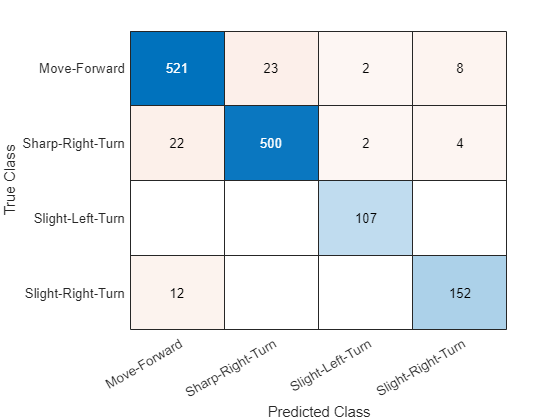

testpred = classify(robonet, testdata);
confusionchart(testlabels, testpred)

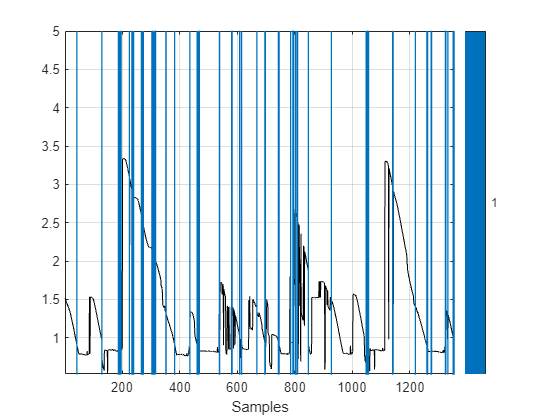

msk = signalMask(testlabels~=testpred);
plotsigroi(msk, testsens, true)

Format the signals for training

function sigout = prepsig(sig)
    sigmatrix = cell2mat(sig);
    sigtranspose = sigmatrix';
    sigout = {sigtranspose};
end

Format the labels for training

function [labelout] = preplabel(label)
    labelcat = categorical(label);
    labeltranspose = labelcat';
    labelout = {labeltranspose};
end